## 1) Carregar o arquivo de áudio e gerar o gráfico do sinal no tempo

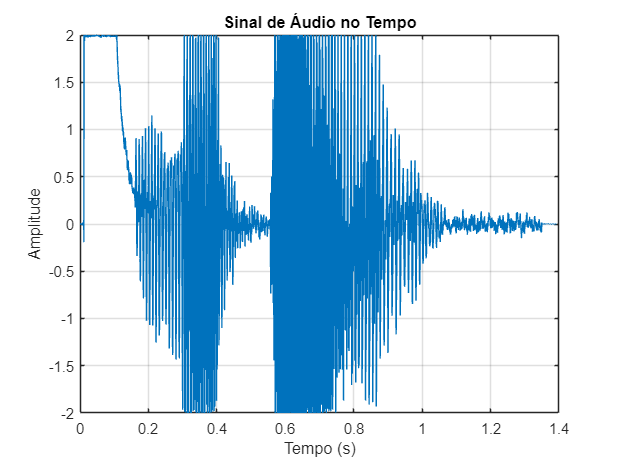

% Carregar o arquivo de áudio
[signal, Fs] = audioread('botao.wav');  
signal = signal(:,1) + signal(:,2);

sound(signal, Fs);

% Definir o vetor de tempo
t = (0:length(signal)-1) / Fs;

% Plotar o gráfico do sinal no tempo
figure;
plot(t, signal);
xlabel('Tempo (s)');
ylabel('Amplitude');
title('Sinal de Áudio no Tempo');
grid on;

## 2) Gerar o gráfico do módulo da Transformada de Fourier em dB

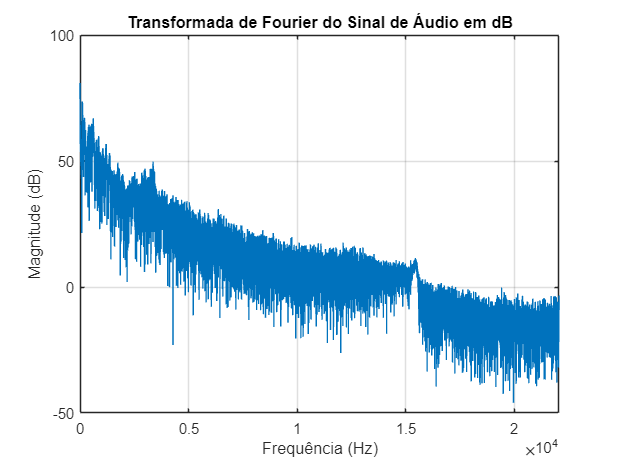

% Transformada de Fourier do sinal de áudio
Y = fft(signal);
n = length(signal);
f = (0:n-1)*(Fs/n);  % Frequências correspondentes
magnitude = abs(Y);

% Transformada em escala dB
magnitude_dB = 20*log10(magnitude);

% Plotar o módulo da Transformada de Fourier
figure;
plot(f, magnitude_dB);
xlabel('Frequência (Hz)');
ylabel('Magnitude (dB)');
title('Transformada de Fourier do Sinal de Áudio em dB');
xlim([0 Fs/2]);  % Limitar até a metade da frequência de amostragem
grid on;

## 3) Adicionar ruído branco gaussiano e gerar gráficos

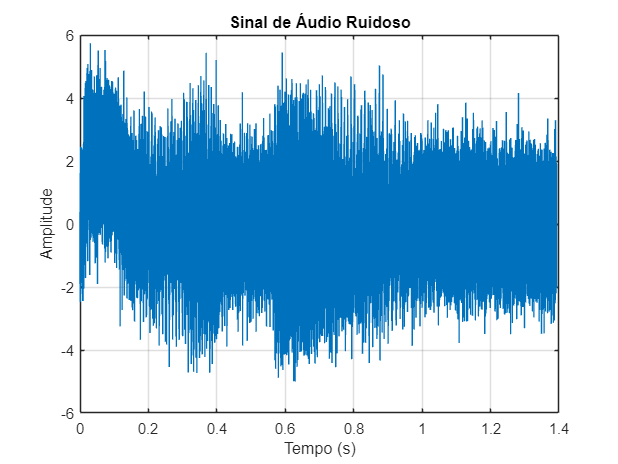

% Adicionar ruído branco gaussiano
noisy_signal = signal + sqrt(1) * randn(size(signal));

% Plotar o sinal ruidoso no tempo
figure;
plot(t, noisy_signal);
xlabel('Tempo (s)');
ylabel('Amplitude');
title('Sinal de Áudio Ruidoso');
grid on;

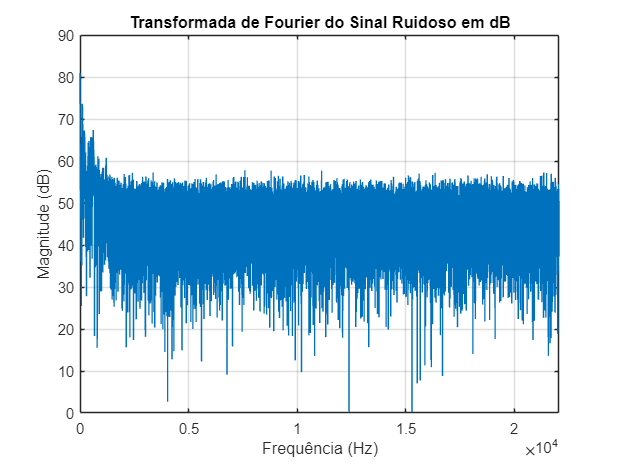

% Transformada de Fourier do sinal ruidoso
Y_noisy = fft(noisy_signal);
magnitude_noisy = abs(Y_noisy);

% Transformada em escala dB
magnitude_noisy_dB = 20*log10(magnitude_noisy);

% Plotar o módulo da Transformada de Fourier do sinal ruidoso
figure;
plot(f, magnitude_noisy_dB);
xlabel('Frequência (Hz)');
ylabel('Magnitude (dB)');
title('Transformada de Fourier do Sinal Ruidoso em dB');
xlim([0 Fs/2]);
grid on;

sound(noisy_signal, Fs);

## 4) Análise do filtro mais adequado e escolha da frequência de corte

% Tipo de filtro: O filtro passa-baixas (PB) é o mais adequado neste caso. O ruído branco tem energia 
% predominante nas frequências mais altas, enquanto o sinal útil está concentrado em frequências mais 
% baixas. O filtro passa-baixas atenuará as frequências mais altas (onde o ruído está) e permitirá a 
% passagem das frequências mais baixas (onde o sinal original está).

% Frequência de corte ideal: A frequência de corte ideal para o filtro parece ser 2 kHz, com base na 
% análise espectral. A maior parte do ruído está em frequências superiores a 2 kHz, enquanto o sinal 
% original possui a maior parte de sua energia abaixo dessa faixa. Isso será suficiente para reduzir 
% o ruído sem prejudicar o conteúdo do áudio original.

f_cutoff = 2000;


## 5) Obter os coeficientes do filtro e visualizar suas respostas

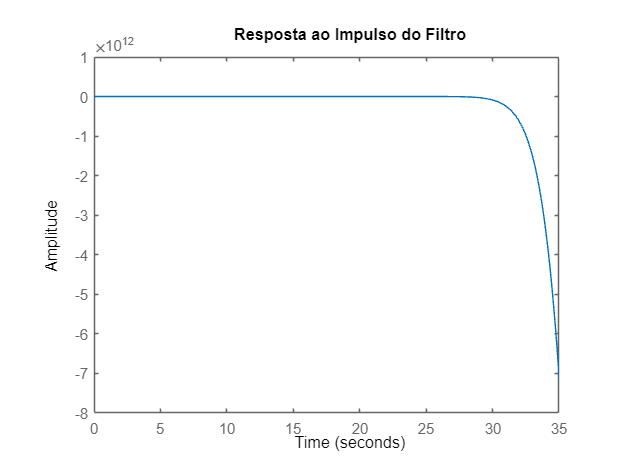

% Design do filtro passa-baixas
[b, a] = butter(6, f_cutoff/(Fs/2), 'low');  % Filtro passa-baixas de ordem 6

% Resposta ao impulso
figure;
impulse(b, a);
title('Resposta ao Impulso do Filtro');

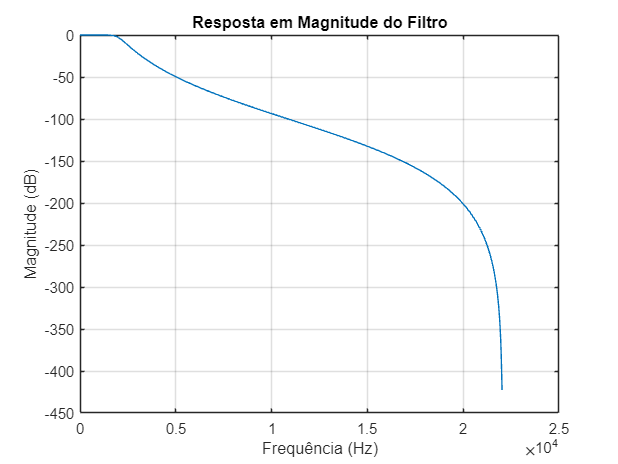

% Resposta em magnitude (dB)
[h, f_h] = freqz(b, a, 1024, Fs);
figure;
plot(f_h, 20*log10(abs(h)));
xlabel('Frequência (Hz)');
ylabel('Magnitude (dB)');
title('Resposta em Magnitude do Filtro');
grid on;

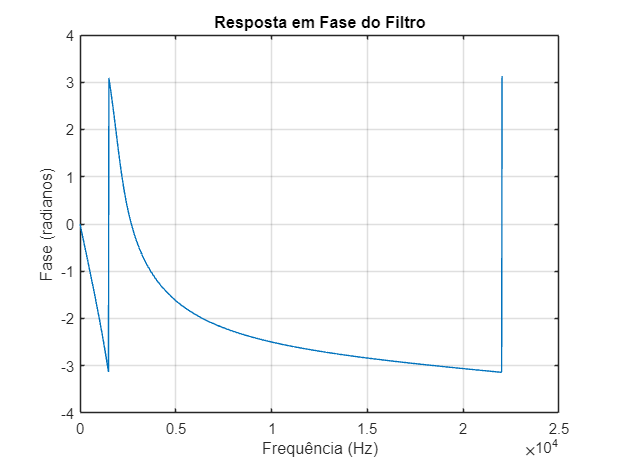

% Resposta em fase
figure;
plot(f_h, angle(h));
xlabel('Frequência (Hz)');
ylabel('Fase (radianos)');
title('Resposta em Fase do Filtro');
grid on;

## 6) Filtrar o sinal ruidoso e gerar gráficos

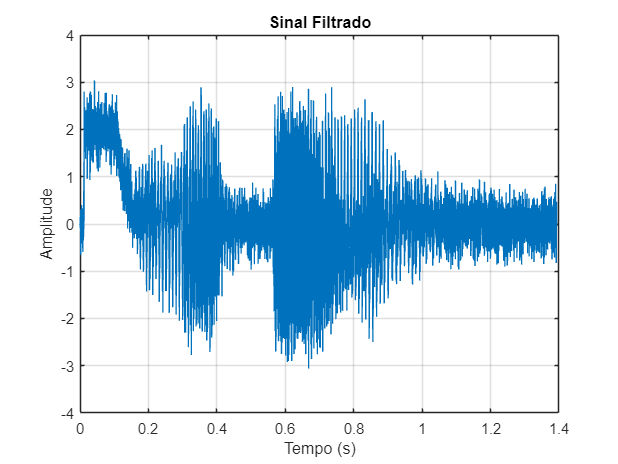

% Filtrar o sinal ruidoso
filtered_signal = filter(b, a, noisy_signal);

% Plotar o sinal filtrado no tempo
figure;
plot(t, filtered_signal);
xlabel('Tempo (s)');
ylabel('Amplitude');
title('Sinal Filtrado');
grid on;

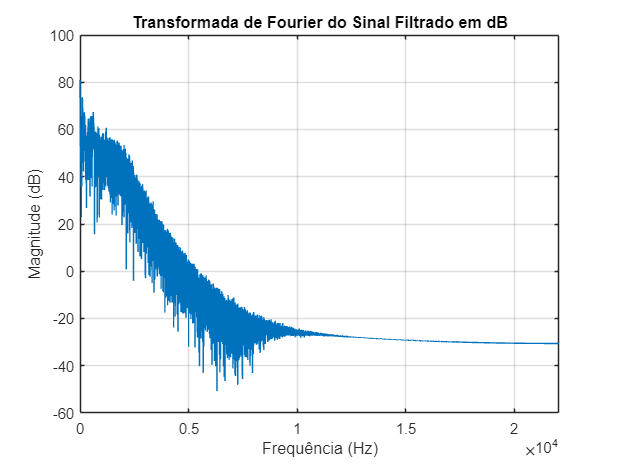

% Transformada de Fourier do sinal filtrado
Y_filtered = fft(filtered_signal);
magnitude_filtered = abs(Y_filtered);

% Transformada em escala dB
magnitude_filtered_dB = 20*log10(magnitude_filtered);

% Plotar o módulo da Transformada de Fourier do sinal filtrado
figure;
plot(f, magnitude_filtered_dB);
xlabel('Frequência (Hz)');
ylabel('Magnitude (dB)');
title('Transformada de Fourier do Sinal Filtrado em dB');
xlim([0 Fs/2]);
grid on;

## 7) Escutar o sinal filtrado e observação

% Escutar o sinal filtrado
sound(filtered_signal, Fs);

% O sinal filtrado apresenta um som mais limpo, com o ruído de alta frequência reduzido.
% As frequências altas do ruído são atenuadas, mas o conteúdo original do áudio é preservado.
% O áudio ficou mais claro e com menos distorção.

## 8) Diagramas de polos e zeros do filtro

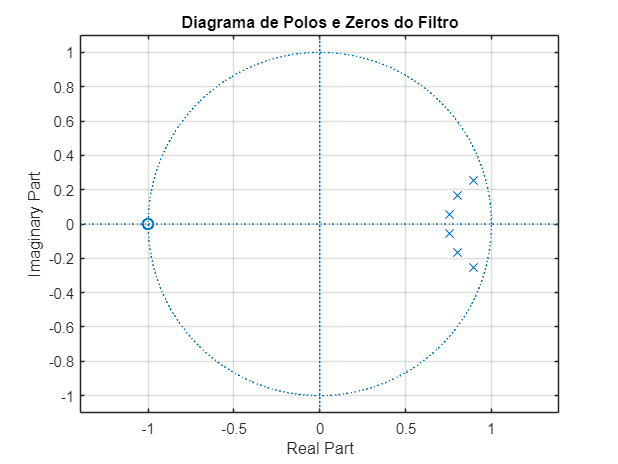

% Diagramas de polos e zeros
figure;
zplane(b, a);
title('Diagrama de Polos e Zeros do Filtro');
grid on;

% O diagrama de polos e zeros mostra que o filtro é passa-baixas (PB).
% O polo próximo ao eixo real e os zeros indicam que o filtro atenua as 
% altas frequências (ruído) e permite a passagem das frequências mais baixas
% (sinal útil). Este comportamento é adequado para reduzir o ruído nas altas
% frequências, preservando o sinal original.